Caricamento dati

clear; clc; close all;

% *** Metti queste due righe all’inizio del tuo script principale
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/1 anno 2023-2024/1 Semestre 2023-2024/Metodi Numerici Avanzati/ProgettoMetodi';
addpath(genpath(projectRoot));                   % tutte le subfolder

% Percorso della cartella in cui salvare i risultati
this_folder = pwd;  % ← Funziona anche se è uno script
results_path = fullfile(this_folder, 'results');

% Crea la cartella se non esiste
if ~exist(results_path, 'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) Caricamento dataset
fprintf('>>> Caricamento dataset...\n');

>>> Caricamento dataset...


tic;
load('dataset/volti_dataset.mat');  % A (m×n), labels...
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.04 s



%% 2) Parametri
[m, n] = size(A);
tol   = 1e-4;
maxit = 1000;

%% 3) Calcolo volto medio
fprintf('>>> Calcolo volto medio...\n');

>>> Calcolo volto medio...


tic;
mean_face = mean(A, 2);
save(fullfile(results_path, 'mean_face.mat'), 'mean_face');
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.01 s



%% 4) Centratura
fprintf('>>> Centratura dati...\n');

>>> Centratura dati...


tic;
A_centered = A - mean_face;
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.01 s



%% 5) SVD con svd_BC
fprintf('>>> Lancio svd_BC (tol=%.1e,maxit=%d)...\n', tol, maxit);

>>> Lancio svd_BC (tol=1.0e-04,maxit=1000)...


tic;
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 410x410 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=410 ... iter=740 time=5.96 s
         [qr_eig] deflazione k=409 ... 

iter=1001 time=9.22 s
         [qr_eig] deflazione k=408 ... 

iter=1001 time=9.53 s
         [qr_eig] deflazione k=407 ... 

iter=1001 time=11.44 s
         [qr_eig] deflazione k=406 ... 

iter=1001 time=12.07 s
         [qr_eig] deflazione k=405 ... 

iter=1001 time=10.58 s
         [qr_eig] deflazione k=404 ... 

iter=1001 time=9.21 s
         [qr_eig] deflazione k=403 ... 

iter=1001 time=9.20 s
         [qr_eig] deflazione k=402 ... 

iter=1001 time=9.32 s
         [qr_eig] deflazione k=401 ... 

iter=1001 time=8.85 s
         [qr_eig] deflazione k=400 ... 

iter=1001 time=8.71 s
         [qr_eig] deflazione k=399 ... 

iter=1001 time=10.40 s
         [qr_eig] deflazione k=398 ... 

iter=1001 time=8.98 s
         [qr_eig] deflazione k=397 ... 

iter=1001 time=8.54 s
         [qr_eig] deflazione k=396 ... 

iter=1001 time=8.74 s
         [qr_eig] deflazione k=395 ... iter=622 time=5.24 s
         [qr_eig] deflazione k=394 ... 

iter=1001 time=8.30 s
         [qr_eig] deflazione k=393 ... 

iter=1001 time=8.63 s
         [qr_eig] deflazione k=392 ... 

iter=1001 time=8.38 s
         [qr_eig] deflazione k=391 ... 

iter=1001 time=8.45 s
         [qr_eig] deflazione k=390 ... 

iter=1001 time=8.87 s
         [qr_eig] deflazione k=389 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=388 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=387 ... 

iter=1001 time=8.36 s
         [qr_eig] deflazione k=386 ... 

iter=1001 time=8.33 s
         [qr_eig] deflazione k=385 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=384 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=383 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=382 ... 

iter=1001 time=8.14 s
         [qr_eig] deflazione k=381 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=380 ... 

iter=1001 time=8.16 s
         [qr_eig] deflazione k=379 ... 

iter=1001 time=8.15 s
         [qr_eig] deflazione k=378 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=377 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=376 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=375 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=374 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=373 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=372 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=371 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=370 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=369 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=368 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=367 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=366 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=365 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=364 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=363 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=362 ... iter=0 time

iter=1001 time=7.45 s
         [qr_eig] deflazione k=360 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=359 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=358 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=357 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=356 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=355 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=354 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=353 ... 

iter=1001 time=7.54 s
         [qr_eig] deflazione k=352 ... 

iter=1001 time=7.47 s
         [qr_eig] deflazione k=351 ... 

iter=1001 time=7.14 s
         [qr_eig] deflazione k=350 ... 

iter=1001 time=7.00 s
         [qr_eig] deflazione k=349 ... 

iter=1001 time=7.05 s
         [qr_eig] deflazione k=348 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=347 ... iter=231 time=1.62 s
         [qr_eig] deflazione k=346 ... 

iter=1001 time=6.86 s
         [qr_eig] deflazione k=345 ... 

iter=1001 time=7.03 s
         [qr_eig] deflazione k=344 ... 

iter=1001 time=6.94 s
         [qr_eig] deflazione k=343 ... 

iter=1001 time=7.27 s
         [qr_eig] deflazione k=342 ... 

iter=1001 time=7.26 s
         [qr_eig] deflazione k=341 ... iter=568 time=4.15 s
         [qr_eig] deflazione k=340 ... 

iter=1001 time=6.57 s
         [qr_eig] deflazione k=339 ... 

iter=1001 time=6.68 s
         [qr_eig] deflazione k=338 ... 

iter=1001 time=6.73 s
         [qr_eig] deflazione k=337 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=336 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=335 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=334 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=333 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=332 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=331 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=330 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=329 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=328 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=327 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=326 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=325 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=324 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=323 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=322 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=321 ... iter=0 time

iter=1001 time=7.62 s
         [qr_eig] deflazione k=311 ... 

iter=1001 time=5.80 s
         [qr_eig] deflazione k=310 ... 

iter=1001 time=5.75 s
         [qr_eig] deflazione k=309 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=308 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=307 ... 

iter=1001 time=5.58 s
         [qr_eig] deflazione k=306 ... 

iter=1001 time=5.97 s
         [qr_eig] deflazione k=305 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=304 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=303 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=302 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=301 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=300 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=299 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=298 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=297 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=296 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=295 ... 

iter=1001 time=5.22 s
         [qr_eig] deflazione k=294 ... 

iter=1001 time=5.14 s
         [qr_eig] deflazione k=293 ... iter=196 time=1.06 s
         [qr_eig] deflazione k=292 ... iter=629 time=10.11 s
         [qr_eig] deflazione k=291 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=290 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=289 ... 

iter=1001 time=5.32 s
         [qr_eig] deflazione k=288 ... 

iter=1001 time=5.28 s
         [qr_eig] deflazione k=287 ... 

iter=1001 time=4.97 s
         [qr_eig] deflazione k=286 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=285 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=284 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=283 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=282 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=281 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=280 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=279 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=278 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=277 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=276 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=275 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=274 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=273 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=272 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=271 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=270 ... iter=0 time

iter=1001 time=3.83 s
         [qr_eig] deflazione k=243 ... 

iter=1001 time=3.96 s
         [qr_eig] deflazione k=242 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=241 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=240 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=239 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=238 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=237 ... 

iter=1001 time=6.61 s
         [qr_eig] deflazione k=236 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=235 ... 

iter=1001 time=3.60 s
         [qr_eig] deflazione k=234 ... 

iter=1001 time=4.14 s
         [qr_eig] deflazione k=233 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=232 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=231 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=230 ... iter=61 time=0.27 s
         [qr_eig] deflazione k=229 ... 

iter=1001 time=3.97 s
         [qr_eig] deflazione k=228 ... 

iter=1001 time=3.49 s
         [qr_eig] deflazione k=227 ... 

iter=1001 time=3.50 s
         [qr_eig] deflazione k=226 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=225 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=224 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=223 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=222 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=221 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=220 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=219 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=218 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=217 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=216 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=215 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=214 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=213 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=212 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=211 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=210 ... iter=0 time

iter=1001 time=2.18 s
         [qr_eig] deflazione k=167 ... 

iter=1001 time=2.15 s
         [qr_eig] deflazione k=166 ... 

iter=1001 time=2.01 s
         [qr_eig] deflazione k=165 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=164 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=163 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=162 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=161 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=160 ... 

iter=1001 time=2.86 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=1.95 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=2.13 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=3.36 s
         [qr_eig] deflazione k=156 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=155 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=154 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=153 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=152 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=151 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=150 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=149 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=148 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=147 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=146 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=145 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=144 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=143 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time

iter=1001 time=1.41 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=131 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=130 ... iter=683 time=0.85 s
         [qr_eig] deflazione k=129 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=709 time=0.87 s
         [qr_eig] deflazione k=125 ... 

iter=1001 time=1.27 s
         [qr_eig] deflazione k=124 ... 

iter=1001 time=1.23 s
         [qr_eig] deflazione k=123 ... 

iter=1001 time=1.14 s
         [qr_eig] deflazione k=122 ... 

iter=1001 time=1.23 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=119 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=118 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=117 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=116 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=115 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=114 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=113 ... 

iter=1001 time=2.07 s
         [qr_eig] deflazione k=112 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=109 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=108 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=100 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=99 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... iter=0 time=0.0

iter=1001 time=0.48 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=75 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=74 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=73 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... 

iter=1001 time=0.42 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.40 s
         [qr_eig] deflazione k=68 ... 

iter=1001 time=0.35 s
         [qr_eig] deflazione k=67 ... 

iter=1001 time=0.36 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=59 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=791 time=0.19 s
         [qr_eig] deflazione k=52 ... 

iter=1001 time=0.20 s
         [qr_eig] deflazione k=51 ... 

iter=1001 time=0.20 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=48 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.18 s
         [qr_eig] deflazione k=46 ... iter=194 time=0.04 s
         [qr_eig] deflazione k=45 ... 

iter=1001 time=0.21 s
         [qr_eig] deflazione k=44 ... 

iter=1001 time=0.16 s
         [qr_eig] deflazione k=43 ... 

iter=1001 time=0.16 s
         [qr_eig] deflazione k=42 ... iter=10 time=0.00 s
         [qr_eig] deflazione k=41 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... 

iter=1001 time=0.12 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=29 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=28 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=27 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=26 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=25 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=24 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=23 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=22 ... 

iter=1001 time=0.06 s
         [qr_eig] deflazione k=21 ... 

iter=1001 time=0.08 s
         [qr_eig] deflazione k=20 ... iter=774 time=0.07 s
         [qr_eig] deflazione k=19 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=18 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=17 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=16 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=15 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=14 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=13 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=12 ... 

iter=1001 time=0.03 s
         [qr_eig] deflazione k=11 ... 

iter=1001 time=0.03 s
         [qr_eig] deflazione k=10 ... iter=11 time=0.00 s
         [qr_eig] deflazione k=9 ... 

iter=1001 time=0.02 s
         [qr_eig] deflazione k=8 ... iter=356 time=0.01 s
         [qr_eig] deflazione k=7 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=6 ... iter=224 time=0.00 s
         [qr_eig] deflazione k=5 ... iter=26 time=0.00 s
         [qr_eig] deflazione k=4 ... iter=209 time=0.00 s
         [qr_eig] deflazione k=3 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=2 ... iter=0 time=0.00 s
      [qr_eig] tutti autovalori estratti.
   [svd_BC] qr_eig completata in 469.11 s
   [svd_BC] costruisco S e U...


t_svd = toc;
fprintf('   svd_BC completata in %.2f s\n', t_svd);

   svd_BC completata in 469.36 s


save(fullfile(results_path, 'svd_data.mat'), 'U', 'S', 'V');

%% 6) Visualizzazione
fprintf('>>> Visualizzazione risultati...\n');

>>> Visualizzazione risultati...



% Volto medio
figure('Name','Volto Medio','NumberTitle','off');
imshow(reshape(mean_face,112,92), []);
title('Volto Medio');
saveas(gcf, fullfile(results_path, 'volto_medio.png'));

% Prime 9 Eigenfaces
figure('Name','Prime 9 Eigenfaces','NumberTitle','off');
for i = 1:9
    subplot(3,3,i);
    imshow(reshape(U(:,i),112,92), []);
    title(sprintf('Eigenface %d', i));
end
saveas(gcf, fullfile(results_path, 'prime9_eigenfaces.png'));

fprintf('>>> Fine script (totale %.2f s)\n', sum([toc - t_svd, t_svd]));

>>> Fine script (totale 474.89 s)


Rete Neurale

%% nn_svd.m (versione con mlp_gradient_descent)
clear; clc; close all;

%% 0) Caricamento e preparazione dati
load('dataset/volti_dataset.mat');    % A, labels
load('results/mean_face.mat');        % mean_face
load('results/svd_data.mat');         % U,S,V

% Parametri SVD
k = 100;
U_k = U(:,1:k);

A_centered = A - mean_face;
projections= U_k' * A_centered;  % [k x n]
    
% Split train/test
num_subjects = max(labels);
train_idx = []; test_idx = [];
for s=1:num_subjects
  idx = find(labels==s);
  idx = idx(randperm(length(idx)));
  train_idx = [train_idx, idx(1:7)];
  test_idx  = [test_idx,  idx(8:end)];
end

X_train = projections(:,train_idx)';   % [n_train x k]
y_train = labels(train_idx)';
X_test  = projections(:,test_idx)';    % [n_test  x k]
y_test  = labels(test_idx)';

% One‐hot encoding
num_classes = num_subjects;
Y_train = zeros(num_classes, length(y_train));
for i=1:length(y_train)
  Y_train(y_train(i),i) = 1;
end

%% 1) Iperparametri MLP
hidden_size   = 128;
epochs        = 100;
learning_rate = 0.005;
dropout_rate  = 0.3;

%% 2) Addestramento tramite gradient descent “artigianale”
fprintf('--- Training MLP via gradient descent ---\n');

--- Training MLP via gradient descent ---


tic;
[W1,b1,W2,b2,loss_hist] = mlp_gradient_descent( ...
    X_train, Y_train, hidden_size, epochs, learning_rate, dropout_rate);

[Epoch  10/100] Loss = 9.4350
[Epoch  20/100] Loss = 0.2856
[Epoch  30/100] Loss = 0.5195
[Epoch  40/100] Loss = 0.3856
[Epoch  50/100] Loss = 0.1265
[Epoch  60/100] Loss = 0.0963
[Epoch  70/100] Loss = 0.4814
[Epoch  80/100] Loss = 0.2888
[Epoch  90/100] Loss = 0.1926
[Epoch 100/100] Loss = 0.0963


fprintf('Training completato in %.2f s\n', toc);

Training completato in 1.12 s



%% 3) Valutazione su test set
X_test_T = X_test';
Z1 = W1 * X_test_T + b1;
A1 = max(0, Z1);
Z2 = W2 * A1 + b2;
Z2 = Z2 - max(Z2,[],1);
expZ = exp(Z2);
A2 = expZ ./ sum(expZ,1);
[~, y_pred] = max(A2,[],1);
acc = mean(y_pred'==y_test)*100;
fprintf('Accuracy on test set: %.2f%%\n', acc);

Accuracy on test set: 92.68%


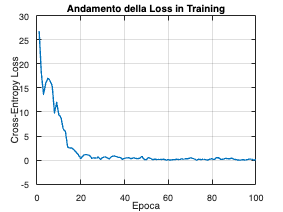


%% 4) plot della loss
figure; plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Cross-Entropy Loss'); grid on;
title('Andamento della Loss in Training');